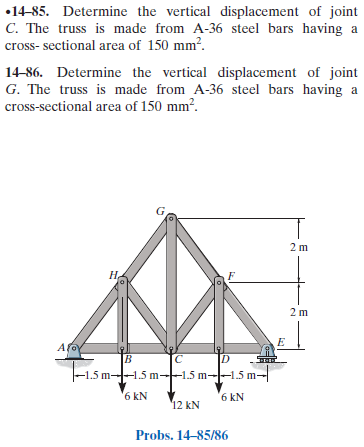

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-85P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-85P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(2/1.5))*u.deg;
jointA = [0 0]*u.m;
jointB = [1.5 0]*u.m;
jointC = [3 0]*u.m;
jointD = [4.5 0]*u.m;
jointE = [6 0]*u.m;
jointF = [4.5 2]*u.m;
jointG = [3 4]*u.m;
jointH = [1.5 2]*u.m;

# member data

E = 200*u.GPa;
A = 150*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Re', {0 'Rey'}, jointE);
t = t.add('concentrated', 'Pb', [0 -6]*u.kN, jointB);
t = t.add('concentrated', 'Pc', [0 -12]*u.kN, jointC);
t = t.add('concentrated', 'Pd', [0 -6]*u.kN, jointD);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('joint', 'F', jointF);
t = t.add('joint', 'G', jointG);
t = t.add('joint', 'H', jointH);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);
t = t.add('member', 'Fef', jointE, jointF, E, A);
t = t.add('member', 'Ffg', jointF, jointG, E, A);
t = t.add('member', 'Fgh', jointG, jointH, E, A);
t = t.add('member', 'Fah', jointA, jointH, E, A);
t = t.add('member', 'Fbh', jointB, jointH, E, A);
t = t.add('member', 'Fch', jointC, jointH, E, A);
t = t.add('member', 'Fcg', jointC, jointG, E, A);
t = t.add('member', 'Fcf', jointC, jointF, E, A);
t = t.add('member', 'Fdf', jointD, jointF, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 3) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0.45\,\mathrm{mm}\\ \mathrm{vB} & -4.62\,\mathrm{mm}\\ \mathrm{uC} & 0.9\,\mathrm{mm}\\ \mathrm{vC} & -5.81\,\mathrm{mm}\\ \mathrm{uD} & 1.35\,\mathrm{mm}\\ \mathrm{vD} & -4.62\,\mathrm{mm}\\ \mathrm{uE} & 1.8\,\mathrm{mm}\\ \mathrm{vE} & 0\\ \mathrm{uF} & -1.74\,\mathrm{mm}\\ \mathrm{vF} & -4.22\,\mathrm{mm}\\ \mathrm{uG} & 0.9\,\mathrm{mm}\\ \mathrm{vG} & -3.41\,\mathrm{mm}\\ \mathrm{uH} & 3.54\,\mathrm{mm}\\ \mathrm{vH} & -4.22\,\mathrm{mm} \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m, 4) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 9.0\,\mathrm{kN}\\ \mathrm{Fbc} & 9.0\,\mathrm{kN}\\ \mathrm{Fcd} & 9.0\,\mathrm{kN}\\ \mathrm{Fde} & 9.0\,\mathrm{kN}\\ \mathrm{Fef} & -15.0\,\mathrm{kN}\\ \mathrm{Ffg} & -11.25\,\mathrm{kN}\\ \mathrm{Fgh} & -11.25\,\mathrm{kN}\\ \mathrm{Fah} & -15.0\,\mathrm{kN}\\ \mathrm{Fbh} & 6.0\,\mathrm{kN}\\ \mathrm{Fch} & -3.75\,\mathrm{kN}\\ \mathrm{Fcg} & 18.0\,\mathrm{kN}\\ \mathrm{Fcf} & -3.75\,\mathrm{kN}\\ \mathrm{Fdf} & 6.0\,\mathrm{kN} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 12\,\mathrm{kN} & 0\\ \text{Re} & 0 & 12\,\mathrm{kN} & 0\\ \mathrm{Pb} & 0 & -6\,\mathrm{kN} & 0\\ \mathrm{Pc} & 0 & -12\,\mathrm{kN} & 0\\ \mathrm{Pd} & 0 & -6\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 9.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fbc} & 9.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fcd} & 9.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fde} & 9.0\,\mathrm{kN} & 0 & 0\\ \mathrm{Fef} & 9.0\,\mathrm{kN} & -12.0\,\mathrm{kN} & 0\\ \mathrm{Ffg} & 6.75\,\mathrm{kN} & -9.0\,\mathrm{kN} & 0\\ \mathrm{Fgh} & 6.75\,\mathrm{kN} & 9.0\,\mathrm{kN} & 0\\ \mathrm{Fah} & -9.0\,\mathrm{kN} & -12.0\,\mathrm{kN} & 0\\ \mathrm{Fbh} & 0 & 6.0\,\mathrm{kN} & 0\\ \mathrm{Fch} & 2.25\,\mathrm{kN} & -3.0\,\mathrm{kN} & 0\\ \mathrm{Fcg} & 0 & 18.0\,\mathrm{kN} & 0\\ \mathrm{Fcf} & -2.25\,\mathrm{kN} & -3.0\,\mathrm{kN} & 0\\ \mathrm{Fdf} & 0 & 6.0\,\mathrm{kN} & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & 12\,\mathrm{kN}\\ \text{Re} & 12\,\mathrm{kN}\\ \mathrm{Pb} & 6\,\mathrm{kN}\\ \mathrm{Pc} & 12\,\mathrm{kN}\\ \mathrm{Pd} & 6\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fcd} & 0\\ \mathrm{Fde} & 0\\ \mathrm{Fef} & 72\,\mathrm{kN}\,m\\ \mathrm{Ffg} & 54\,\mathrm{kN}\,m\\ \mathrm{Fgh} & 0\\ \mathrm{Fah} & 0\\ \mathrm{Fbh} & 9\,\mathrm{kN}\,m\\ \mathrm{Fch} & 9\,\mathrm{kN}\,m\\ \mathrm{Fcg} & 54\,\mathrm{kN}\,m\\ \mathrm{Fcf} & 9\,\mathrm{kN}\,m\\ \mathrm{Fdf} & 27\,\mathrm{kN}\,m \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \text{Re} & 0 & 0 & 72\,\mathrm{kN}\,m\\ \mathrm{Pb} & 0 & 0 & -9\,\mathrm{kN}\,m\\ \mathrm{Pc} & 0 & 0 & -36\,\mathrm{kN}\,m\\ \mathrm{Pd} & 0 & 0 & -27\,\mathrm{kN}\,m \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fcd} & 0 & 0 & 0\\ \mathrm{Fde} & 0 & 0 & 0\\ \mathrm{Fef} & 0 & 0 & -72\,\mathrm{kN}\,m\\ \mathrm{Ffg} & 0 & 0 & -54\,\mathrm{kN}\,m\\ \mathrm{Fgh} & 0 & 0 & 0\\ \mathrm{Fah} & 0 & 0 & 0\\ \mathrm{Fbh} & 0 & 0 & 9\,\mathrm{kN}\,m\\ \mathrm{Fch} & 0 & 0 & -9\,\mathrm{kN}\,m\\ \mathrm{Fcg} & 0 & 0 & 54\,\mathrm{kN}\,m\\ \mathrm{Fcf} & 0 & 0 & -9\,\mathrm{kN}\,m\\ \mathrm{Fdf} & 0 & 0 & 27\,\mathrm{kN}\,m \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \text{Re} & 72\,\mathrm{kN}\,m\\ \mathrm{Pb} & 9\,\mathrm{kN}\,m\\ \mathrm{Pc} & 36\,\mathrm{kN}\,m\\ \mathrm{Pd} & 27\,\mathrm{kN}\,m \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c ma_f_c_vpa la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;